# PRACTICA 3 Restauración de Material Fonográfico

CARLOS BURGOS PÉREZ - ANDRES TORRES LOPEZ

EJERCICIO 1

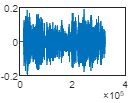

clear;
alfa = 1;
[a, fs]= audioread("P3_sound2.wav");
a = a';
Senal_Limpia = filtroWienner(a, fs, alfa);

sound(Senal_Limpia, fs)

FUNCIONES LOCALES

function [Senal_Limpia] = filtroWienner(a, fs, alfa)
NumMuestrasRuido = 9500; % Obtenido viendolo en la grafica
NumMuestrasAudio = length(a);
TamBloque = 2^(nextpow2(0.02*fs));

NumVentanasRuido = fix((NumMuestrasRuido/TamBloque));
%dENSDAD espectral ruido gausiano es uno aprox

% Cogemos el primer bloque de ruido que sra de la muestra 1 hasta el tamaño de bloque,
% eso lo multiplico por la ventana de hanning y obtengo un bloque de ruido, luego le hago la
% fft, el modulo, lo elevo al cuadrado y ya tengo la densidad espectral de potencia de ruido
% de un bloque, paso al siguiente bloque, que va de tamañobloque/2 + 1 a 2*tamañobloque
% finalmente se suman todas las densidades de ruido obtenidas y se hace la media
Ruido = a(1 : NumMuestrasRuido);

% PrimerBloque de uno  a 1024, el siguiente será 1024/2 + 1
PrtotalRuido = 0;
VentanaHanningR = 2*NumVentanasRuido - 1;
V = hanning(1024);
V = V';
for i = 1 : NumVentanasRuido
    PosInicial = 512*(i - 1) + 1;
    PrRuido = Ruido(PosInicial : PosInicial + 1024 - 1);
    PrRuido = PrRuido.*V;
    PrRuido = abs(fft(PrRuido, 2047)); %1024*2-1
    PrRuido = PrRuido.^2;
    PrtotalRuido = PrtotalRuido + PrRuido;
end
Pr = PrtotalRuido/NumVentanasRuido;
plot(PrtotalRuido);

NumBloques = fix(length(a)/TamBloque);
VentanaHanningA = 2*NumBloques - 1;
V = hanning(TamBloque);
V = V';
PrtotalAudio = 0;
Senal_Limpia=zeros(((VentanaHanningA+1)*TamBloque/2) + 1024,1);

for i = 1 : VentanaHanningA
    PosInicial = 512*(i - 1) + 1;
    Pos_final=PosInicial+TamBloque-1;
    PrAudio = a(PosInicial : Pos_final);
    PrAudio = PrAudio.*V;
    AudioEnventanado = PrAudio;
    PrAudio = abs(fft(AudioEnventanado, 2047));
    PrAudio = PrAudio.^2;
    PAuxAudio = PrAudio;
    aux = PrAudio < 1;
    PAuxAudio(aux) = 1;
    
    H = (PrAudio - alfa.*Pr)./PAuxAudio;
    X = H.*fft(AudioEnventanado, 2047);
    x = ifft(X);
    x = x';
    
    Senal_Limpia(PosInicial : Pos_final + 1023) = x + Senal_Limpia(PosInicial : Pos_final + 1023);
end
plot(Senal_Limpia)
end